# Ball in a Loop: Physics Simulation

## Introduction

Classical approaches for solving problems from mechanics often use analytical methods to find answers to particular questions. While this is very helpful in understanding the underlying laws, there is somehow a disconnect between these results and the experiment which is not static but dynamic. Further drawbacks are that once the physics get more complicated it is harder or maybe even impossible to find analytic solutions. In that case one has to use numerical approaches or simulations to solve the problem. In this example we will apply basic numerical methods to solve the trajectory of a ball in a loop.

For this we will set up a looping track and calculate the forces that act on a ball that travels through the loop. Knowing these forces at every time step, allows to solve the equation of motion iteratively and find the trajectory. For simplicity, we assume that there is no friction.

## Setting up the Track

The following code snippet defines the parameters used for the simulation:

rampAngle=65; %Define the slope of the ramp (angle in degree)
loopRadius= 1.5;
startHeight=7.5;

Based on these parameters we can plot the track.

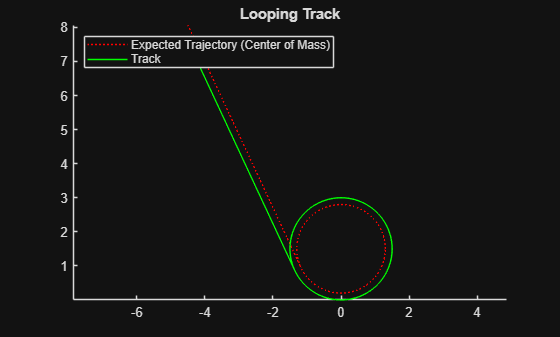

warning('off','all')
ballRadius=0.2;
[ballTrack,loopTrack,t1,t2,x1,x0,s1,y1]=prepTrack(rampAngle,ballRadius,loopRadius,startHeight);
figure
hold on
%plot(x1,y1,'ko') %touching point
plot(t1,ballTrack,':r')
plot(t2,loopTrack,'-g')
t=linspace(0,2*pi);
plot((loopRadius-ballRadius)*cos(t),(loopRadius-ballRadius)*sin(t)+loopRadius, ":r") %plot the circle
plot(loopRadius*cos(t),loopRadius*sin(t)+loopRadius,'-g') %plot the circle

%xlim([-5 5])
%ylim([0 8])
axis equal
title('Looping Track')
legend("Expected Trajectory (Center of Mass)", "Track", 'Location', "northwest")
hold off

## Equations of motion and their iterative simulation

The normal and tangential force acting on the ball are described as:

$\vec{F}_{n}=-\vec{F}_g \cos(\alpha) \hat{e}_n=F_g\cos(\alpha) \left(\begin{array}{c} \sin(\alpha) \\ \cos(\alpha) \end{array}\right)$, $\vec{F}_{t}=\vec{F}_g\ \sin(\alpha) \hat{e}_t=F_g\sin(\alpha) \left(\begin{array}{c} \cos(\alpha) \\ -\sin(\alpha) \end{array}\right)$

Note: So far we assumed that the angle of the slope is positive... in order to have a continuous variable for the ramp and the loop we chose this to be negative initially... This will change some of the signs.

%functions for visualization
fgnx=@(t) cos(t)*sin(t); %gravity component along normal (x direction)
fgny=@(t) -cos(t)*cos(t); %gravity component along normal (y direction)
fgtx=@(t) -sin(t)*cos(t);
fgty=@(t) -sin(t)*sin(t);

Using this description we can solve the equation of motion $F=m\ddot{x}$ iteratively. We only have to integrate it twice.

First integration yields the velocity:

$v_{i+1}=v_i+\frac{F_g}{m}\sin(\alpha) \left(\begin{array}{c} -\cos(\alpha) \\ -\sin(\alpha) \end{array}\right)\cdot t_s$.

Second integration gives the current position:

$x_{i+1}=x_i+v_i\cdot t_s+\frac{1}{2}\frac{F_g}{m}\sin(\alpha) \left(\begin{array}{c} -\cos(\alpha) \\ -\sin(\alpha) \end{array}\right)\cdot t^2_s$.

Once we are inside the loop, we have to check if the gravity component along the loop normal direction is not bigger than the required zentripetal force. Otherwise the ball will fall. This can be described more formally as:

$(\vec{F}_{zp}-\vec{F}_{g,n})\cdot \hat{n}_{loop}>0$, where $\vec{F}_{zp}=\frac{mv^2}{R_{loop}}\left(\begin{array}{c} -\sin(\alpha) \\ \cos(\alpha) \end{array}\right)$ is the zentripetal force (pointing to the center of the loop) and $\vec{F}_{g,n}=mg\cdot \cos(\alpha)\left(\begin{array}{c} \sin(\alpha) \\ -\cos(\alpha) \end{array}\right)$.

As long as this condition is met, the equations above are modified to:

- $v_{i+1}=v_i+\frac{F_g}{m}\sin(\alpha) \left(\begin{array}{c} -\cos(\alpha) \\ -\sin(\alpha) \end{array}\right)\cdot t_s + \frac{v^2}{R_{loop}}\left(\begin{array}{c} -\sin(\alpha) \\ \cos(\alpha) \end{array}\right)\cdot t_s$.

- 
$$x_{i+1}=x_i+v_i\cdot t_s+\frac{1}{2}\frac{F_g}{m}\sin(\alpha) \left(\begin{array}{c} -\cos(\alpha) \\ -\sin(\alpha) \end{array}\right)\cdot t^2_s+\frac{1}{2}\frac{v^2}{R_{loop}}\left(\begin{array}{c} -\sin{\alpha} \\ \cos{\alpha} \end{array}\right)\cdot t^2_s$$


Otherwise, the resulting force would simply be the gravitation $F_{g}=mg$.

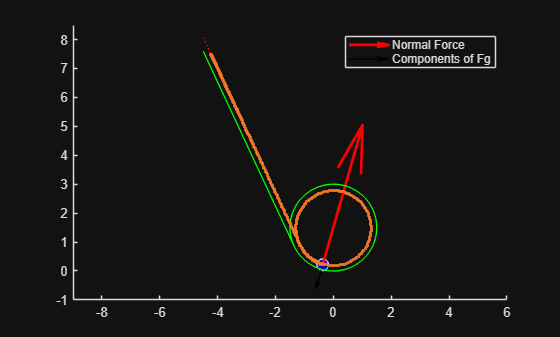

rb=ballRadius;
Rloop=loopRadius-rb;
% calculate the starting position depending on the given parameters
% we know the equation of the ramp from above -> solve it for h

% the length of the path till we reach the loop is

si=0;
vi=[0; 0];
%for s0>s>0 the forces are determined by the simple case I

%have to write an iterative solver:
%define the timesteps:
xi=zeros(2,1000);
si=zeros(1,1000);
vn=si;
vi=xi;
ti=zeros(1,15001);
xi(:,1)=[x0; startHeight]; % this is our starting point
fallen=false;
alpha=@(s) (s-s1)/Rloop-rampAngle/180*pi;

figure

%Plot initialization:
pb=rectangle('Position', [xi(1,1)-ballRadius, xi(2,1)-ballRadius, 2*ballRadius, 2*ballRadius], 'Curvature', [1 1], 'FaceColor', 'b');
hold on

q4=quiver(xi(1,1),xi(2,1),-fgnx(-rampAngle/180*pi),-fgny(-rampAngle/180*pi),'r-','MaxHeadSize',5,'LineWidth',2); %normal force

q1=quiver(xi(1,1),xi(2,1),fgnx(-rampAngle/180*pi),fgny(-rampAngle/180*pi),'k-','MaxHeadSize',5,'LineWidth',1); %gravity normal
legend({"Normal Force","Components of Fg"})
legend('AutoUpdate', 'off','Location','northeast');
q2=quiver(xi(1,1),xi(2,1), fgtx(-rampAngle/180*pi), fgty(-rampAngle/180*pi), 'k-','MaxHeadSize',5,'LineWidth',1); %gravity tangential
q3=quiver(xi(1,1),xi(2,1),0,0,'k-','MaxHeadSize',5,'LineWidth',1); % gravity

t=linspace(0,2*pi);
ptl=plot((loopRadius-rb)*cos(t),(loopRadius-rb)*sin(t)+loopRadius,':r'); %plot the circle
pl=plot(loopRadius*cos(t),loopRadius*sin(t)+loopRadius,'-g'); %plot the loop


%t=linspace(xi(1,1),x1);
ptr=plot(t1,ballTrack,':r');
pr=plot(t2,loopTrack,'-g');
% ptr=plot(t,subs(a,a,slp)*t+eval(subs(dr,[R a ro],[loopRadius slp ballRadius])),':r');
% pr=plot(t,subs(a,a,slp)*t+eval(subs(dr,[R a ro],[loopRadius slp 0])),'-g');

pbt=plot(xi(1,1),xi(2,1),'.-'); %ball trajectory

%ylimits
if xi(2,1)>loopRadius*2
    ylim([-1 xi(2,1)+1]);
else
    ylim([-1 loopRadius*2+1]);
end

axis equal
u=0; %number that tracks revolutions...
%start to solve the equation of motion
for i=1:2000
    ts=0.01;
    g=9.81;
    fi=1/3;%impact from inertia
    ti(i+1)=ti(i)+ts;
    
    if si(i) < s1
        vi(:,i+1)=vi(:,i)+fi*(g*[0;-1]+g*cosd(rampAngle)*[sind(rampAngle);cosd(rampAngle)])*ts;
        xi(:,i+1)=xi(:,i)+vi(:,i)*ts+0.5*fi*(g*[0;-1]+g*cosd(rampAngle)*[sind(rampAngle);cosd(rampAngle)])*ts^2;
        si(i+1)=si(i)+norm(xi(:,i+1)-xi(:,i));
        vn(i+1)=norm(vi(:,i+1));
        
        pb.Position=[xi(1,i)-ballRadius, xi(2,i)-ballRadius, 2*ballRadius, 2*ballRadius];

        %update quiver plots
        %gravity normal
        q1.XData=xi(1,i);
        q1.YData=xi(2,i);
        q1.UData=fgnx(-rampAngle/180*pi);
        q1.VData=fgny(-rampAngle/180*pi);

        q4.XData=xi(1,i);
        q4.YData=xi(2,i);
        q4.UData=-fgnx(-rampAngle/180*pi);
        q4.VData=-fgny(-rampAngle/180*pi);
        
        %gravity tangential
        q2.XData=xi(1,i);
        q2.YData=xi(2,i);
        q2.UData=fgtx(-rampAngle/180*pi);
        q2.VData=fgty(-rampAngle/180*pi);
    
    else
        %calculate the needed normal force
        an=norm(vi(:,i))^2/Rloop*[-sin(alpha(si(i))); cos(alpha(si(i)))]-g*[fgnx(alpha(si(i))); fgny(alpha(si(i)))];
        
        if fallen==false && an'*[-sin(alpha(si(i))); cos(alpha(si(i)))]>0 % obj still in contact
            %use the resulting tangential and zentripetal force
            vi(:,i+1)=vi(:,i)+fi*g*[fgtx(alpha(si(i))); fgty(alpha(si(i)))]*ts+norm(vi(:,i))^2/Rloop*[-sin(alpha(si(i))); cos(alpha(si(i)))]*ts;
            xi(:,i+1)=xi(:,i)+vi(:,i)*ts+0.5*fi*g*[fgtx(alpha(si(i))); fgty(alpha(si(i)))]*ts^2+0.5*norm(vi(:,i))^2/Rloop*[-sin(alpha(si(i))); cos(alpha(si(i)))]*ts^2;
            si(i+1)=si(i)+norm(xi(:,i+1)-xi(:,i));
            vn(i+1)=norm(vi(:,i+1));
            
            pb.Position=[xi(1,i)-ballRadius, xi(2,i)-ballRadius, 2*ballRadius, 2*ballRadius];

            %update quiver plots
            %gravity normal
            q1.XData=xi(1,i);
            q1.YData=xi(2,i);
            q1.UData=fgnx(alpha(si(i))); 
            q1.VData=fgny(alpha(si(i)));

            q4.XData=xi(1,i);
            q4.YData=xi(2,i);
            q4.UData=an(1)/g;
            q4.VData=an(2)/g;
            
            %gravity tangential
            q2.XData=xi(1,i);
            q2.YData=xi(2,i);
            q2.UData=fgtx(alpha(si(i)));
            q2.VData=fgty(alpha(si(i)));

            % gravity
            q3.XData=xi(1,i);
            q3.YData=xi(2,i);
            q3.UData=0;
            q3.VData=0;

        else
            fallen=true;
            vi(:,i+1)=vi(:,i)+g*[0; -1]*ts;
            xi(:,i+1)=xi(:,i)+vi(:,i)*ts+0.5*g*[0; -1]*ts^2;
            si(i+1)=si(i)+norm(xi(:,i+1)-xi(:,i));
            vn(i+1)=norm(vi(:,i+1));
            pb.Position=[xi(1,i)-ballRadius, xi(2,i)-ballRadius, 2*ballRadius, 2*ballRadius];
            
            %gravity normal
            q1.XData=xi(1,i);
            q1.YData=xi(2,i);
            q1.UData=0; 
            q1.VData=0;

            %gravity tangential
            q2.XData=xi(1,i);
            q2.YData=xi(2,i);
            q2.UData=0;
            q2.VData=0;


            % gravity
            q3.XData=xi(1,i);
            q3.YData=xi(2,i);
            q3.UData=0;
            q3.VData=-1;
        end
    end

    
    if i>=3
        if (xi(2,i)-xi(2,i-1))/(xi(1,i)-xi(1,i-1)) < 0 && (xi(2,i-1)-xi(2,i-2))/(xi(1,i-1)-xi(1,i-2)) > 0 
            u=u+0.5;
        end
    end

    if xi(2,i)<=-1 || u==1.5
        break
    end

    pbt.XData=xi(1,1:i);
    pbt.YData=xi(2,1:i);
  
    pause(0.01)

end
hold off

function [ballTrack,loopTrack,t,t2,x1,x0,s1,y1]=prepTrack(rampAngle,ballRadius,loopRadius,startHeight)
% This function contains explanations how to derive the equations for the track description.
% The equation for the ramp is h_ramp(x)=ax+b, where a, is the slope and b is the displacement from the origin on the y-axis. The slope is related to the inclination angle a as a=-tan(a). Please note the minus sign, which denotes that the slope is falling.
    syms xr R ro a b %set symbolic variables
    slp=-tand(rampAngle);
    lin=a*xr+b;
    % The lower part of the loop itself is described by h_loop(x)=R-\sqrt(R^2-x^2), whereas the ramp can be parametrized with h_ramp=ax+b.
    eqn=R-sqrt((R-ro)^2-xr^2);
    % In order to connect the two parts of the track, we have to solve the two equations for . I.e. one has to solve the system:
    % 1.) h'_ramp(x)=h'_loop(x) and 2.) h_ramp(x)=h_loop(x)
    % This will further give us the touching point, the point where the ramp is ending into the loop.
    
    %i) find the touching point on the circle
    derv=diff(eqn,xr); %differentiate the loop equation
    eq2=derv==a; %set it equal to the slope of the ramp
    res=solve(eq2,xr); % and solve for x
    
    x1=eval(subs(res(1),[R a ro],[loopRadius slp ballRadius])); %substitute the values of the variables and evaluate the expression to get the solution as a double
    x2=eval(subs(res(1),[R a ro],[loopRadius slp 0]));

    %ii) find b so that the two parts of the track coincide for x=xt
    dr=solve(subs(lin,xr,res(1))==subs(eqn,xr,res(1)),b);
    
    y1=eval(subs(eqn,[R xr ro],[loopRadius x1 ballRadius])); %end position of the ramp.. beginning of the loop
    
    xs=-startHeight/tand(rampAngle)-1;
    t=linspace(xs,x1);

    ballTrack=subs(a,a,slp)*t+eval(subs(dr,[R a ro],[loopRadius slp ballRadius]));
    t2=linspace(xs,x2);
    loopTrack=subs(a,a,slp)*t2+eval(subs(dr,[R a ro],[loopRadius slp 0]));
    x0=(startHeight-eval(subs(dr,[R a ro],[loopRadius slp ballRadius])))/eval(subs(a,a,slp));
    s1=sqrt((x0-x1)^2+(startHeight-eval(subs(eqn,[R xr ro],[loopRadius x1 ballRadius])))^2);
end